clear;clc;
% --- paths (use your original logic) ---
if exist('I:\', 'dir')
    input_path = 'I:\My Drive\Data\New Data\EEG epoched\';
    base_output_path = 'C:\Users\sinad\OneDrive - Georgia Institute of Technology\Dr. Sederberg MaTRIX Lab\temporal_criticality_of_latent_results';
elseif exist('H:\', 'dir')
    input_path = 'H:\My Drive\Data\New Data\EEG epoched\';
    base_output_path = 'C:\Users\sinad\OneDrive - Georgia Institute of Technology\Dr. Sederberg MaTRIX Lab\temporal_criticality_of_latent_results';
elseif exist('G:\', 'dir')
    input_path = 'G:\My Drive\Data\New Data\EEG epoched\';
    base_output_path = 'C:\Users\sdabiri\OneDrive - Georgia Institute of Technology\Dr. Sederberg MaTRIX Lab\temporal_criticality_of_latent_results';
else
    error('Unknown system: Cannot determine input and output paths.');
end
output_path = fullfile(base_output_path, 'longitudinal_dPCA');

if ~exist(output_path, 'dir')
    mkdir(output_path);
    fprintf('Created new output directory: %s\n', output_path);
end

conditions = {'BLA','BLT','P1','P2','P3'}; %,'BLT','P1','P2','P3'
num_ch = 32;
expected_num_time = 1792; % sample count per epoch (your value)
fs = []; % will set from EEG.srate on first load
time_ms_eeg = [];

## 1.1 Load and import file as EEGLAB matrix

data_all_conds = struct();

% Loop through the conditions
for c = 1:length(conditions)
    condition = conditions{c};
    in_dir = fullfile(input_path, condition);
    set_files = dir(fullfile(in_dir, '*.set'));
    names_sorted = sort(cellstr({set_files.name})');
    
    if isempty(names_sorted)
        fprintf('No .set files for %s — skipping\n', condition);
        continue;
    end
    
    % Load excel file paths for P2 and P3 ONCE per condition
    if strcmp(condition, 'P2')
        excel_file_path = fullfile(input_path, 'Indexes for P2.xlsx');
        epoch_trials_p2_500ms = readmatrix(excel_file_path, 'Sheet', 'Audio onset with 500 ms tactile');
        epoch_trials_p2_2000ms = readmatrix(excel_file_path, 'Sheet', 'Audio onset with 2000 ms tactil');
    elseif strcmp(condition, 'P3')
        excel_file_path = fullfile(input_path, 'Indexes for P3.xlsx');
        epoch_trials_p3_500ms = readmatrix(excel_file_path, 'Sheet', 'Audio onset with 500 ms tactile');
        epoch_trials_p3_missing = readmatrix(excel_file_path, 'Sheet', 'Audio onset with missing tactil');
    end

    % --- NEW: Loop through ALL subjects for this condition ---
    for s = 1:length(names_sorted)
        file_to_load = names_sorted{s}; 
        fprintf('Loading Subj %d/%d (%s) for condition: %s\n', s, length(names_sorted), file_to_load, condition);
        
        EEG = pop_loadset('filename', file_to_load, 'filepath', in_dir);
        if isempty(fs), fs = EEG.srate; end
        
        if isempty(time_ms_eeg)
            time_ms_eeg = linspace(0, 3.5 , size(EEG.data, 2)); 
        end
        
        % Extract data and store in a cell array to avoid dimension mismatch
        if ismember(condition, {'BLA', 'BLT', 'P1'})
            epoch_trials = 1:2:EEG.trials;
            data_all_conds.(condition){s} = EEG.data(:, :, epoch_trials);
            
        elseif strcmp(condition, 'P2')
            epoch_trials_p2 = 1:2:EEG.trials;     
            data_all_conds.(condition){s} = EEG.data(:, :, epoch_trials_p2);
            data_all_conds.P2_500{s}      = EEG.data(:, :, epoch_trials_p2_500ms);
            data_all_conds.P2_2000{s}     = EEG.data(:, :, epoch_trials_p2_2000ms);
            
        elseif strcmp(condition, 'P3')
            epoch_trials_p3 = 1:2:EEG.trials;
            data_all_conds.(condition){s}   = EEG.data(:, :, epoch_trials_p3);
            data_all_conds.P3_500{s}        = EEG.data(:, :, epoch_trials_p3_500ms);
            data_all_conds.P3_missing{s}    = EEG.data(:, :, epoch_trials_p3_missing);
        end
    end
end

Loading Subj 1/14 (binepochs filtered ICArej BLAAvgBOS10.set) for condition: BLA


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS10.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS10.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 2/14 (binepochs filtered ICArej BLAAvgBOS11.set) for condition: BLA


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS11.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS11.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 3/14 (binepochs filtered ICArej BLAAvgBOS12.set) for condition: BLA


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS12.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS12.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 4/14 (binepochs filtered ICArej BLAAvgBOS13.set) for condition: BLA


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS13.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS13.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 5/14 (binepochs filtered ICArej BLAAvgBOS15.set) for condition: BLA


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS15.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS15.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 6/14 (binepochs filtered ICArej BLAAvgBOS16.set) for condition: BLA


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS16.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS16.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 7/14 (binepochs filtered ICArej BLAAvgBOS17.set) for condition: BLA


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS17.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS17.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 8/14 (binepochs filtered ICArej BLAAvgBOS2.set) for condition: BLA


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS2.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS2.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 9/14 (binepochs filtered ICArej BLAAvgBOS3.set) for condition: BLA


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS3.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS3.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 10/14 (binepochs filtered ICArej BLAAvgBOS5.set) for condition: BLA


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS5.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS5.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 11/14 (binepochs filtered ICArej BLAAvgBOS6.set) for condition: BLA


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS6.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS6.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 12/14 (binepochs filtered ICArej BLAAvgBOS7.set) for condition: BLA


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS7.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS7.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 13/14 (binepochs filtered ICArej BLAAvgBOS8.set) for condition: BLA


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS8.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS8.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 14/14 (binepochs filtered ICArej BLAAvgBOS9.set) for condition: BLA


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS9.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS9.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 1/14 (binepochs filtered ICArej BLTAvgBOS10.set) for condition: BLT


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS10.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS10.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 2/14 (binepochs filtered ICArej BLTAvgBOS11.set) for condition: BLT


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS11.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS11.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 3/14 (binepochs filtered ICArej BLTAvgBOS12.set) for condition: BLT


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS12.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS12.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 4/14 (binepochs filtered ICArej BLTAvgBOS13.set) for condition: BLT


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS13.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS13.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 5/14 (binepochs filtered ICArej BLTAvgBOS15.set) for condition: BLT


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS15.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS15.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 6/14 (binepochs filtered ICArej BLTAvgBOS16.set) for condition: BLT


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS16.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS16.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 7/14 (binepochs filtered ICArej BLTAvgBOS17.set) for condition: BLT


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS17.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS17.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 8/14 (binepochs filtered ICArej BLTAvgBOS2.set) for condition: BLT


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS2.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS2.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 9/14 (binepochs filtered ICArej BLTAvgBOS3.set) for condition: BLT


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS3.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS3.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 10/14 (binepochs filtered ICArej BLTAvgBOS5.set) for condition: BLT


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS5.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS5.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 11/14 (binepochs filtered ICArej BLTAvgBOS6.set) for condition: BLT


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS6.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS6.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 12/14 (binepochs filtered ICArej BLTAvgBOS7.set) for condition: BLT


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS7.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS7.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 13/14 (binepochs filtered ICArej BLTAvgBOS8.set) for condition: BLT


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS8.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS8.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 14/14 (binepochs filtered ICArej BLTAvgBOS9.set) for condition: BLT


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS9.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS9.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 1/14 (binepochs filtered ICArej P1AvgBOS10.set) for condition: P1


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS10.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS10.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 2/14 (binepochs filtered ICArej P1AvgBOS11.set) for condition: P1


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS11.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS11.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 3/14 (binepochs filtered ICArej P1AvgBOS12.set) for condition: P1


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS12.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS12.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 4/14 (binepochs filtered ICArej P1AvgBOS13.set) for condition: P1


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS13.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS13.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 5/14 (binepochs filtered ICArej P1AvgBOS15.set) for condition: P1


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS15.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS15.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 6/14 (binepochs filtered ICArej P1AvgBOS16.set) for condition: P1


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS16.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS16.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 7/14 (binepochs filtered ICArej P1AvgBOS17.set) for condition: P1


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS17.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS17.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 8/14 (binepochs filtered ICArej P1AvgBOS2.set) for condition: P1


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS2.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS2.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 9/14 (binepochs filtered ICArej P1AvgBOS3.set) for condition: P1


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS3.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS3.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 10/14 (binepochs filtered ICArej P1AvgBOS5.set) for condition: P1


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS5.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS5.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 11/14 (binepochs filtered ICArej P1AvgBOS6.set) for condition: P1


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS6.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS6.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 12/14 (binepochs filtered ICArej P1AvgBOS7.set) for condition: P1


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS7.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS7.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 13/14 (binepochs filtered ICArej P1AvgBOS8.set) for condition: P1


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS8.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS8.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 14/14 (binepochs filtered ICArej P1AvgBOS9.set) for condition: P1


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS9.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS9.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 1/14 (binepochs filtered ICArej P2AvgBOS10.set) for condition: P2


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS10.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS10.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 2/14 (binepochs filtered ICArej P2AvgBOS11.set) for condition: P2


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS11.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS11.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 3/14 (binepochs filtered ICArej P2AvgBOS12.set) for condition: P2


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS12.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS12.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 4/14 (binepochs filtered ICArej P2AvgBOS13.set) for condition: P2


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS13.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS13.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 5/14 (binepochs filtered ICArej P2AvgBOS15.set) for condition: P2


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS15.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS15.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 6/14 (binepochs filtered ICArej P2AvgBOS16.set) for condition: P2


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS16.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS16.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 7/14 (binepochs filtered ICArej P2AvgBOS17.set) for condition: P2


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS17.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS17.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 8/14 (binepochs filtered ICArej P2AvgBOS2.set) for condition: P2


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS2.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS2.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 9/14 (binepochs filtered ICArej P2AvgBOS3.set) for condition: P2


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS3.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS3.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 10/14 (binepochs filtered ICArej P2AvgBOS5.set) for condition: P2


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS5.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS5.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 11/14 (binepochs filtered ICArej P2AvgBOS6.set) for condition: P2


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS6.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS6.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 12/14 (binepochs filtered ICArej P2AvgBOS7.set) for condition: P2


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS7.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS7.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 13/14 (binepochs filtered ICArej P2AvgBOS8.set) for condition: P2


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS8.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS8.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 14/14 (binepochs filtered ICArej P2AvgBOS9.set) for condition: P2


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS9.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS9.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 1/14 (binepochs filtered ICArej P3AvgBOS10.set) for condition: P3


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS10.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS10.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 2/14 (binepochs filtered ICArej P3AvgBOS11.set) for condition: P3


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS11.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS11.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 3/14 (binepochs filtered ICArej P3AvgBOS12.set) for condition: P3


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS12.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS12.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 4/14 (binepochs filtered ICArej P3AvgBOS13.set) for condition: P3


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS13.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS13.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 5/14 (binepochs filtered ICArej P3AvgBOS15.set) for condition: P3


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS15.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS15.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 6/14 (binepochs filtered ICArej P3AvgBOS16.set) for condition: P3


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS16.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS16.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 7/14 (binepochs filtered ICArej P3AvgBOS17.set) for condition: P3


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS17.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS17.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 8/14 (binepochs filtered ICArej P3AvgBOS2.set) for condition: P3


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS2.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS2.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 9/14 (binepochs filtered ICArej P3AvgBOS3.set) for condition: P3


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS3.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS3.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 10/14 (binepochs filtered ICArej P3AvgBOS5.set) for condition: P3


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS5.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS5.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 11/14 (binepochs filtered ICArej P3AvgBOS6.set) for condition: P3


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS6.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS6.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 12/14 (binepochs filtered ICArej P3AvgBOS7.set) for condition: P3


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS7.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS7.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 13/14 (binepochs filtered ICArej P3AvgBOS8.set) for condition: P3


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS8.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS8.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 14/14 (binepochs filtered ICArej P3AvgBOS9.set) for condition: P3


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS9.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS9.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


## 1.2 Visualizing the conditions raw data

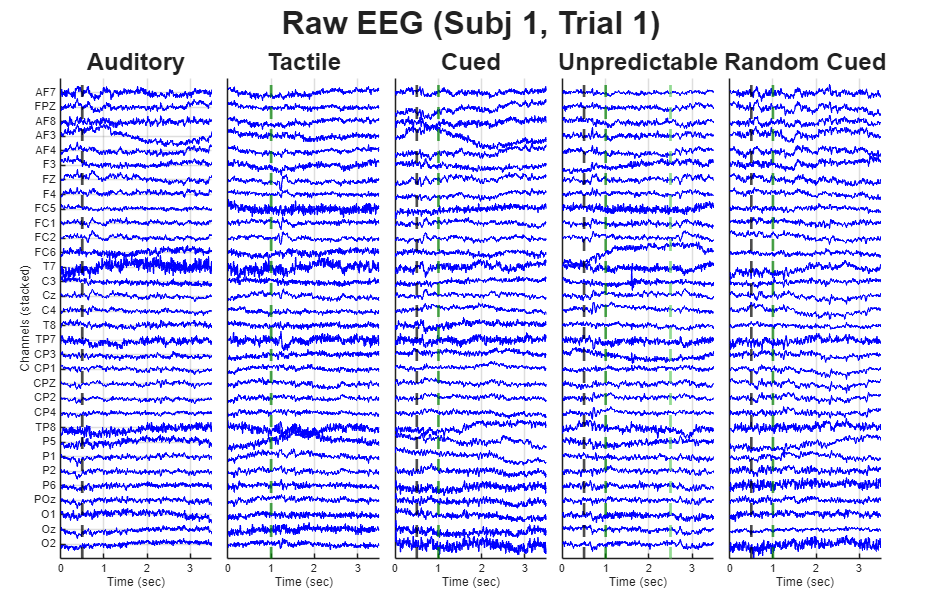

%% Visualizing Specific Trial for a Specific Subject
target_trial = 1; 
target_subject = 1; 

if exist('EEG', 'var') && isfield(EEG, 'chanlocs')
    display_channels_str = {EEG.chanlocs.labels};
else
    display_channels_str = cellstr(num2str((1:size(data_all_conds.BLT{1}, 1))')); 
end

num_channels_plot = length(display_channels_str);
plot_conds = fieldnames(data_all_conds);
num_conds = length(conditions); % Just plotting the base conditions for now

figure('Position',[50 50 2200 1400])
t = tiledlayout(1, num_conds, 'TileSpacing', 'compact', 'Padding', 'compact');
title(t, sprintf('Raw EEG (Subj %d, Trial %d)', target_subject, target_trial), 'FontSize', 24, 'FontWeight', 'bold');

offset = 30; 
tick_positions = (num_channels_plot - (1:num_channels_plot)) * offset;

for c = 1:num_conds
    cond_name = conditions{c};
    
    % Access the cell for the subject, then slice the 3rd dimension for the trial
    data_to_plot = data_all_conds.(cond_name){target_subject}(:, :, target_trial);
    
    nexttile;
    hold on
    for ch = 1:num_channels_plot
        plot(time_ms_eeg, data_to_plot(ch, :) + (num_channels_plot - ch)*offset, 'b', 'LineWidth', 1.0);
    end
    
    if strcmp(cond_name, 'BLT')
        xline(1.0, '--', 'Color', [0 0.5 0], 'LineWidth', 2);
    elseif any(strcmp(cond_name, {'P1','P3'}))
        xline(0.5, 'k--', 'LineWidth', 2);
        xline(1.0, '--', 'Color', [0 0.5 0], 'LineWidth', 2);
    elseif strcmp(cond_name, 'P2')
        xline(0.5, 'k--', 'LineWidth', 2);
        xline(1.0, '--', 'Color', [0 0.5 0], 'LineWidth', 2);
        xline(2.5, '--', 'Color', [0.4 0.8 0.4], 'LineWidth', 2);
    else
        xline(0.5, 'k--', 'LineWidth', 2);
    end
    
    hold off
    xlim([min(time_ms_eeg), max(time_ms_eeg)]); 
    ylim([-offset, num_channels_plot*offset]);
    xlabel('Time (sec)'); 
    
    if c == 1
        ylabel('Channels (stacked)');
        yticks(flip(tick_positions));
        yticklabels(flip(string(display_channels_str)));
    else
        yticks([]);
    end
    if ismember(cond_name, 'BLA')
        plot_name = 'Auditory';
    elseif ismember(cond_name, 'BLT')
        plot_name = 'Tactile';    
    elseif ismember(cond_name, 'P1')
        plot_name = 'Cued';
    elseif ismember(cond_name, 'P2')
        plot_name = 'Unpredictable';
    elseif ismember(cond_name, 'P3')
        plot_name = 'Random Cued';
    end
    title(plot_name, 'FontSize', 18);
    grid on;
end

disp('Calculating averages across trials and subjects...');

Calculating averages across trials and subjects...



cond_names = fieldnames(data_all_conds);
data_subj_avg = struct();
data_grand_avg = struct();
data_grand_std = struct();

for i = 1:length(cond_names)
    c_name = cond_names{i};
    num_subjects = length(data_all_conds.(c_name));
    
    % 1. Average across trials for EACH subject
    % Preallocate [Channels x Time x Subjects]
    subj_avg_matrix = zeros(num_ch, length(time_ms_eeg), num_subjects);
    
    for s = 1:num_subjects
        % Average across dim 3 (trials)
        subj_avg_matrix(:,:,s) = mean(data_all_conds.(c_name){s}, 3, 'omitnan');
    end
    data_subj_avg.(c_name) = subj_avg_matrix;
    
    % 2. Average across subjects (Grand Average)
    data_grand_avg.(c_name) = mean(subj_avg_matrix, 3, 'omitnan');
    
    % 3. Standard Deviation across subjects (for shaded error bars)
    data_grand_std.(c_name) = std(subj_avg_matrix, 0, 3, 'omitnan');
end

%% Visualizing Grand Average with STD Shading
channels_to_plot = {'AF3', 'F3', 'FZ', 'FC5', 'FC1',  'T7', 'C3', 'Cz', 'C4', 'T8', 'TP7', 'CP3', 'CP1',  'P5', 'P1', 'O1', 'Oz', 'O2'};

[~, chan_idx] = ismember(channels_to_plot, display_channels_str);
valid_mask = chan_idx > 0;
chan_idx = chan_idx(valid_mask);
display_channels_str = channels_to_plot(valid_mask);

num_channels_plot = length(display_channels_str);
num_conds = length(conditions); 


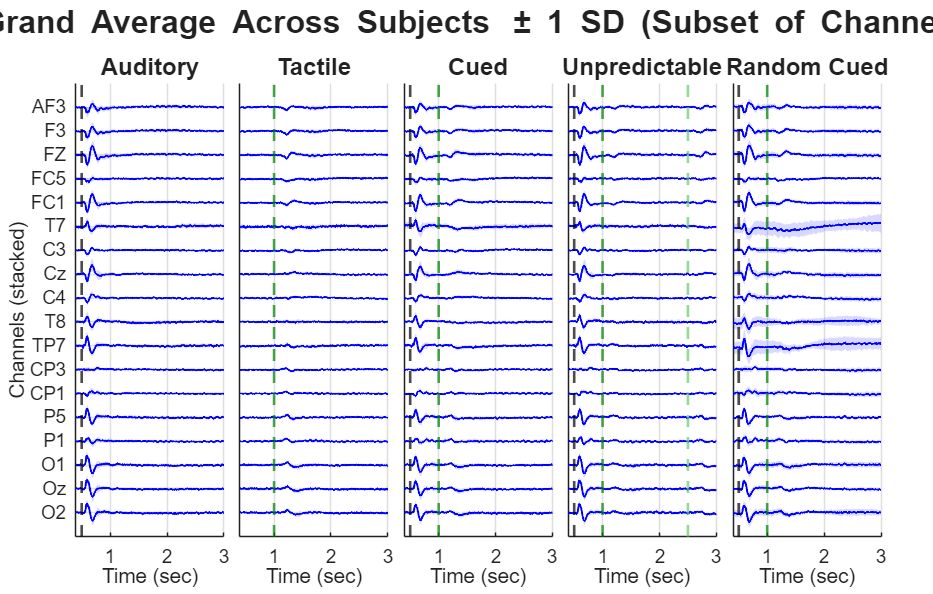

figure('Position',[50 50 2200 1400])
t = tiledlayout(1, num_conds, 'TileSpacing', 'compact', 'Padding', 'compact');
title(t, 'Grand Average Across Subjects \pm 1 SD (Subset of Channels)', 'FontSize', 24, 'FontWeight', 'bold');

offset = 15; 
tick_positions = (num_channels_plot - (1:num_channels_plot)) * offset;
time_fill = [time_ms_eeg, fliplr(time_ms_eeg)]; % X-axis for shading

for c = 1:num_conds
    cond_name = conditions{c};
    
    nexttile;
    hold on
    
    for ch = 1:num_channels_plot
        actual_ch = chan_idx(ch);
        y_shift = (num_channels_plot - ch) * offset;
        
        % Extract mean and std for this specific channel
        mu = data_grand_avg.(cond_name)(actual_ch, :) + y_shift;
        sigma = data_grand_std.(cond_name)(actual_ch, :);
        
        % Create boundaries for the shaded standard deviation
        y_bound = [mu + sigma, fliplr(mu - sigma)];
        
        % Plot Shaded STD Area first (so it sits behind the line)
        fill(time_fill, y_bound, 'b', 'FaceAlpha', 0.15, 'EdgeColor', 'none', 'HandleVisibility', 'off');
        
        % Plot Mean Line
        plot(time_ms_eeg, mu, 'b', 'LineWidth', 1.5);
    end
    
    % Add Vertical Event Lines
    if strcmp(cond_name, 'BLT')
        xline(1.0, '--', 'Color', [0 0.5 0], 'LineWidth', 2);
    elseif any(strcmp(cond_name, {'P1','P3'}))
        xline(0.5, 'k--', 'LineWidth', 2);
        xline(1.0, '--', 'Color', [0 0.5 0], 'LineWidth', 2);
    elseif strcmp(cond_name, 'P2')
        xline(0.5, 'k--', 'LineWidth', 2);
        xline(1.0, '--', 'Color', [0 0.5 0], 'LineWidth', 2);
        xline(2.5, '--', 'Color', [0.4 0.8 0.4], 'LineWidth', 2);
    else
        xline(0.5, 'k--', 'LineWidth', 2);
    end
    
    hold off
    xlim([0.4, 3]); 
    ylim([-offset, num_channels_plot*offset]);
    xlabel('Time (sec)'); 
    
    if c == 1
        ylabel('Channels (stacked)');
        yticks(flip(tick_positions));
        yticklabels(flip(string(display_channels_str)));
    else
        yticks([]); 
    end
    
    set(gca,'FontSize',14);
    if ismember(cond_name, 'BLA')
        plot_name = 'Auditory';
    elseif ismember(cond_name, 'BLT')
        plot_name = 'Tactile';    
    elseif ismember(cond_name, 'P1')
        plot_name = 'Cued';
    elseif ismember(cond_name, 'P2')
        plot_name = 'Unpredictable';
    elseif ismember(cond_name, 'P3')
        plot_name = 'Random Cued';
    end
    title(plot_name, 'FontSize', 18);
    grid on;
end

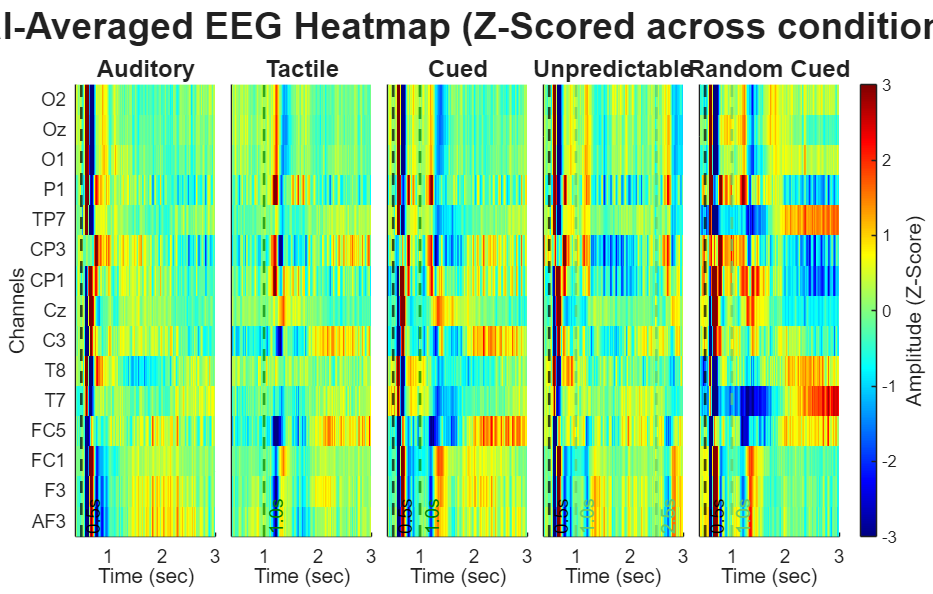

% 1. Define the specific channels you want to plot
channels_to_plot = {'AF3', 'F3', 'Fz', 'FC1', 'FC5', 'T7', 'T8', 'C3', 'Cz', 'CP1', 'CP3', 'TP7', 'P1', 'O1', 'Oz', 'O2'};

% Safely extract all 32 channel labels 
if exist('EEG', 'var') && isfield(EEG, 'chanlocs')
    all_channels_str = {EEG.chanlocs.labels};
else
    % Fallback if EEG structure isn't in the workspace
    all_channels_str = cellstr(num2str((1:size(data_grand_avg.BLT, 1))')); 
end

% 2. Find the indices of the requested channels within the full list
[~, chan_idx] = ismember(channels_to_plot, all_channels_str);

% Safety check: remove any channels from the list that weren't found
valid_mask = chan_idx > 0;
chan_idx = chan_idx(valid_mask);
display_channels_str = channels_to_plot(valid_mask);

num_channels_plot = length(display_channels_str);

% Define your observed conditions (ensure 'BLA' is included if you use it in the loop)
conditions = {'BLA', 'BLT', 'P1', 'P2', 'P3'};
num_conds = length(conditions); 

% --- NEW: Z-score across all conditions per channel ---
% Concatenate all condition data to compute global mean and std per channel
concat_data = [];
for c = 1:num_conds
    cond_name = conditions{c};
    concat_data = [concat_data, data_grand_avg.(cond_name)];
end

% Calculate mean and std specifically for the selected channels
mu_chan = mean(concat_data(chan_idx, :), 2);
sigma_chan = std(concat_data(chan_idx, :), 0, 2);

% Prevent division by zero if a channel is completely flat
sigma_chan(sigma_chan == 0) = 1; 

% Set color limits to typical Z-score bounds (±3 standard deviations)
color_limits = [-3, 3]; 

% Widen the figure to comfortably fit side-by-side plots
figure('Position',[50 50 2200 1400])
t = tiledlayout(1, num_conds, 'TileSpacing', 'compact', 'Padding', 'compact');
title(t, 'Trial-Averaged EEG Heatmap (Z-Scored across conditions)', 'FontSize', 28, 'FontWeight', 'bold');

% Custom colors for the event lines
dark_green  = [0 0.5 0];
light_green = [0.4 0.8 0.4];

% Loop through all conditions to generate the tiles dynamically
for c = 1:num_conds
    cond_name = conditions{c};
    
    % --- Extract and Z-score the Data ---
    raw_data = data_grand_avg.(cond_name)(chan_idx, :);
    data_to_plot = (raw_data - mu_chan) ./ sigma_chan; % Z-score calculation
    
    nexttile;
    hold on;
    
    % 1. Plot the Heatmap
    imagesc(time_ms_eeg, 1:num_channels_plot, data_to_plot);
    
    % Apply the z-score color limits
    clim(color_limits); 
    
    % 2. Add Vertical Event Lines
    if strcmp(cond_name, 'BLT')
        xline(1.0, '--', '1.0s', 'Color', dark_green, 'LineWidth', 2, 'FontSize', 14, 'LabelVerticalAlignment', 'bottom');
    else
        xline(0.5, 'k--', '0.5s', 'LineWidth', 2, 'FontSize', 14, 'LabelVerticalAlignment', 'bottom');
    end
    
    if ismember(cond_name, 'P1')
        xline(1.0, '--', '1.0s', 'Color', dark_green, 'LineWidth', 2, 'FontSize', 14, 'LabelVerticalAlignment', 'bottom');
    elseif strcmp(cond_name, 'P2')
        xline(1.0, '--', '1.0s', 'Color', light_green, 'LineWidth', 2, 'FontSize', 14, 'LabelVerticalAlignment', 'bottom');
        xline(2.5, '--', '2.5s', 'Color', light_green, 'LineWidth', 2, 'FontSize', 14, 'LabelVerticalAlignment', 'bottom');
    elseif strcmp(cond_name, 'P3')
        xline(1.0, '--', '1.0s', 'Color', light_green, 'LineWidth', 2, 'FontSize', 14, 'LabelVerticalAlignment', 'bottom');
    end
    
    hold off;
    
    % Fit axes
    xlim([0.4, 3]); 
    ylim([0.5, num_channels_plot + 0.5]); 
    xlabel('Time (sec)'); 
    
    % Y-Axis formatting
    if c == 1
        ylabel('Channels');
        yticks(1:num_channels_plot);
        yticklabels(display_channels_str);
    else
        yticks([]); 
    end
    
    set(gca, 'YDir', 'normal', 'FontSize', 14);
    
    % Custom Titles
    if ismember(cond_name, 'BLA')
        plot_name = 'Auditory';
    elseif ismember(cond_name, 'BLT')
        plot_name = 'Tactile';    
    elseif ismember(cond_name, 'P1')
        plot_name = 'Cued';
    elseif ismember(cond_name, 'P2')
        plot_name = 'Unpredictable';
    elseif ismember(cond_name, 'P3')
        plot_name = 'Random Cued';
    else
        plot_name = cond_name;
    end
    title(sprintf('%s', plot_name), 'FontSize', 18);
    
end

% Use a divergent colormap suitable for Z-scores
colormap('jet'); 
cb = colorbar;
cb.Layout.Tile = 'east'; 
cb.Label.String = 'Amplitude (Z-Score)';
cb.Label.FontSize = 16;

## 2.0 & 2.1 Task-Specific dPCA Models

%% 2.0 & 2.1 Task-Specific dPCA Models (Option A: Shared Spaces)
disp('Building Tensors and Running Task-Specific dPCA Models...');

Building Tensors and Running Task-Specific dPCA Models...



% Define the 3 Task Spaces and their participating conditions
dpca_configs = struct();
dpca_configs.MS   = {'BLA', 'BLT', 'P1'};
dpca_configs.Temp = {'P1', 'P2_500', 'P2_2000', 'P2'};
dpca_configs.Stim = {'P1', 'P3_500', 'P3_missing', 'P3'};

model_names = fieldnames(dpca_configs);
dpca_models = struct();
num_comps = 10; % Number of components to extract

% Extract dimensions using P1 as a reference
[num_ch, nTime] = size(data_grand_avg.P1);
margNames = {'Condition', 'Time', 'Cond x Time Interaction'};

for m = 1:length(model_names)
    m_name = model_names{m};
    conds = dpca_configs.(m_name);
    num_c = length(conds);
    
    fprintf('\n=== Running dPCA for %s Space ===\n', m_name);
    
    % 1. Pre-allocate the trial-averaged dPCA Tensor
    % Size: [Channels x Conditions x Time]
    X_avg = zeros(num_ch, num_c, nTime);
    
    % 2. Populate the Tensor
    for c = 1:num_c
        c_name = conds{c};
        X_avg(:, c, :) = data_grand_avg.(c_name);
    end
    
    % 3. Calculate Global Mean for this specific space
    % dPCA automatically centers the data, so we must track the exact 
    % mean to project our data properly later.
    X_flat = reshape(X_avg, num_ch, []);
    mu = mean(X_flat, 2);
    
    % 4. Run dPCA (W = Decoder, V = Encoder)
    % We pass only the trial-averaged tensor. The script will safely 
    % catch the singular matrix warning and apply lambda = 1e-10.
    [W, V, whichMarg] = dpca(X_avg, num_comps);
    
    % 5. Store the model weights and parameters
    dpca_models.(m_name).W = W;
    dpca_models.(m_name).V = V;
    dpca_models.(m_name).mu = mu;
    
    % Find dominant marginalization for labeling plots
    dominant_marg = zeros(1, num_comps);
    for comp = 1:num_comps
        [~, dominant_marg(comp)] = max(whichMarg(:, comp));
    end
    dpca_models.(m_name).dominant_marg = dominant_marg;
    
    % 6. Store the extracted projections (Time Courses)
    for c = 1:num_c
        c_name = conds{c};
        % Project: W' * (Condition Data - Shared Mean)
        dpca_models.(m_name).projections.(c_name) = W' * (data_grand_avg.(c_name) - mu);
    end
end


=== Running dPCA for MS Space ===


Matrix close to singular, using tiny regularization, lambda = 1e-10
Matrix close to singular, using tiny regularization, lambda = 1e-10
Matrix close to singular, using tiny regularization, lambda = 1e-10



=== Running dPCA for Temp Space ===


Matrix close to singular, using tiny regularization, lambda = 1e-10
Matrix close to singular, using tiny regularization, lambda = 1e-10
Matrix close to singular, using tiny regularization, lambda = 1e-10



=== Running dPCA for Stim Space ===


Matrix close to singular, using tiny regularization, lambda = 1e-10
Matrix close to singular, using tiny regularization, lambda = 1e-10
Matrix close to singular, using tiny regularization, lambda = 1e-10


disp('dPCA Task Spaces complete.');

dPCA Task Spaces complete.


## 2.2 Visualizing Top 4 dPCA Components Overlaid

disp('Plotting Top 4 dPCA Components for each Task Space...');

Plotting Top 4 dPCA Components for each Task Space...


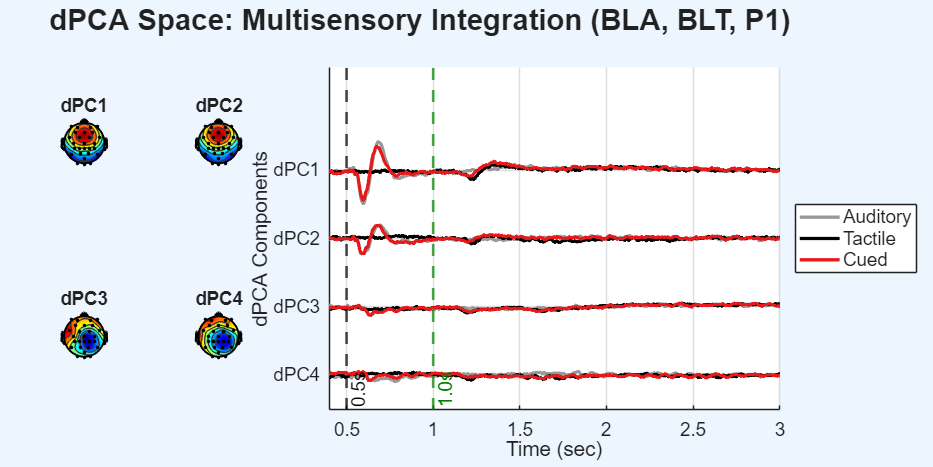

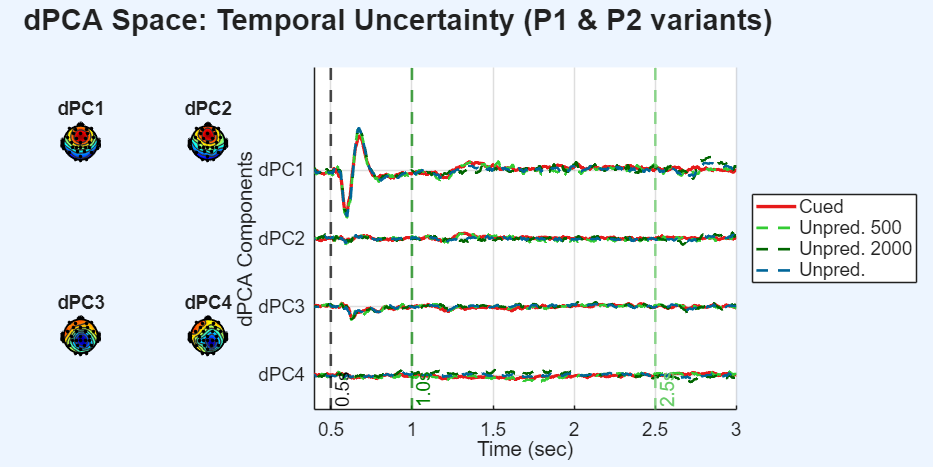

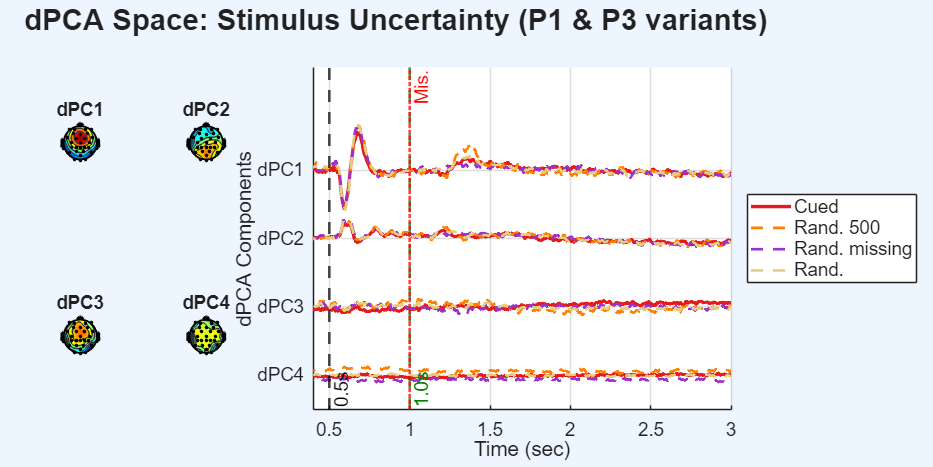


num_comps_plot = 4;
comp_offset = 30; % Adjust this value if the temporal peaks overlap too much
tick_positions = (num_comps_plot - (1:num_comps_plot)) * comp_offset;

% Custom Colors
color_map = struct(...
    'BLA', [0.6 0.6 0.6], 'BLT', [0.0 0.0 0.0], 'P1',  [0.9 0.1 0.1], ...
    'P2', [0.0 0.4 0.6], 'P2_500', [0.2 0.8 0.2], 'P2_2000', [0.0 0.4 0.0], ...
    'P3', [0.9 0.8 0.5], 'P3_500', [1.0 0.5 0.0], 'P3_missing', [0.6 0.2 0.8] ...
);

dark_green = [0 0.5 0];
light_green = [0.4 0.8 0.4];

warning('off', 'all'); % Suppress topoplot layout warnings

for m = 1:length(model_names)
    m_name = model_names{m};
    conds = dpca_configs.(m_name);
    
    figure('Position',[50 50 2000 1000], 'Name', sprintf('dPCA Shared Space: %s', m_name));
    
    % We use a 2x6 layout. 
    % Topoplots will take up the first 2 columns (a 2x2 grid).
    % Time courses will take up the remaining 4 columns.
    t = tiledlayout(2, 6, 'TileSpacing', 'compact', 'Padding', 'compact');
    
    % Dynamic Title
    if strcmp(m_name, 'MS')
        title(t, 'dPCA Space: Multisensory Integration (BLA, BLT, P1)', 'FontSize', 22, 'FontWeight', 'bold');
    elseif strcmp(m_name, 'Temp')
        title(t, 'dPCA Space: Temporal Uncertainty (P1 & P2 variants)', 'FontSize', 22, 'FontWeight', 'bold');
    elseif strcmp(m_name, 'Stim')
        title(t, 'dPCA Space: Stimulus Uncertainty (P1 & P3 variants)', 'FontSize', 22, 'FontWeight', 'bold');
    end
    
    % 1. Plot the 4 Topoplots explicitly in the left-hand columns
    % We map comp 1-4 to specific tile numbers: 1, 2, 7, 8
    topo_tiles = [1, 2, 7, 8]; 
    for comp = 1:num_comps_plot
        nexttile(topo_tiles(comp));
        topoplot(dpca_models.(m_name).V(:, comp), EEG.chanlocs, 'electrodes', 'on');
        marg_idx = dpca_models.(m_name).dominant_marg(comp);
        title(sprintf('dPC%d', comp), 'FontSize', 14);
    end
    
    % 2. Plot the Stacked Time Courses on the right
    % We tell it to start at tile 3 and span 2 rows by 4 columns
    nexttile(3, [2 4]); 
    hold on;
    h_lines = gobjects(1, length(conds)); 
    
    for c = 1:length(conds)
        c_name = conds{c};
        if isfield(color_map, c_name), clr = color_map.(c_name); else, clr = rand(1,3); end
        
        % Solid lines for base conditions, dashed lines for variants
        if ismember(c_name, {'BLA', 'BLT', 'P1'}), l_style = '-'; l_width = 2.5;
        else, l_style = '--'; l_width = 2.0; end
        
        comp_to_plot = dpca_models.(m_name).projections.(c_name)(1:num_comps_plot, :);
        
        % Stack components vertically
        for comp_idx = 1:num_comps_plot
            y_offset = (num_comps_plot - comp_idx) * comp_offset;
            p = plot(time_ms_eeg, comp_to_plot(comp_idx, :) + y_offset, ...
                'Color', clr, 'LineStyle', l_style, 'LineWidth', l_width);
            if comp_idx == 1, h_lines(c) = p; end
        end
    end
    
    % Add Vertical Event Lines dynamically
    xline(0.5, 'k--', '0.5s', 'LineWidth', 2, 'FontSize', 14, 'LabelVerticalAlignment', 'bottom'); 
    
    if strcmp(m_name, 'MS')
        xline(1.0, '--', '1.0s', 'Color', dark_green, 'LineWidth', 2, 'FontSize', 14, 'LabelVerticalAlignment', 'bottom');
    elseif strcmp(m_name, 'Temp')
        xline(1.0, '--', '1.0s', 'Color', dark_green, 'LineWidth', 2, 'FontSize', 14, 'LabelVerticalAlignment', 'bottom');
        xline(2.5, '--', '2.5s', 'Color', light_green, 'LineWidth', 2, 'FontSize', 14, 'LabelVerticalAlignment', 'bottom');
    elseif strcmp(m_name, 'Stim')
        xline(1.0, '--', '1.0s', 'Color', dark_green, 'LineWidth', 2, 'FontSize', 14, 'LabelVerticalAlignment', 'bottom');
        xline(1.0, 'r:', 'Mis.', 'LineWidth', 2, 'FontSize', 14, 'LabelVerticalAlignment', 'top');
    end
    hold off;
    
    % Axis Formatting
    xlim([0.4, 3]); 
    ylim([-comp_offset*0.5, num_comps_plot*comp_offset + comp_offset*0.5]);
    xlabel('Time (sec)', 'FontSize', 16);
    ylabel('dPCA Components', 'FontSize', 16);
    yticks(flip(tick_positions));
    yticklabels(flip(arrayfun(@(x) sprintf('dPC%d', x), 1:num_comps_plot, 'UniformOutput', false)));
    set(gca,'FontSize',14);
    grid on;
    
    % Clean up text for the Legend
    clean_names = strrep(strrep(strrep(strrep(strrep(strrep(conds, ...
        'BLA', 'Auditory'), 'BLT', 'Tactile'), 'P1', 'Cued'), ...
        'P2', 'Unpred.'), 'P3', 'Rand.'), '_', ' ');
    legend(h_lines, clean_names, 'Location', 'eastoutside', 'FontSize', 14);
end


warning('on', 'all');
disp('dPCA visualization complete.');

dPCA visualization complete.


## 3.0 Cosine Similarity Setup & Calculation

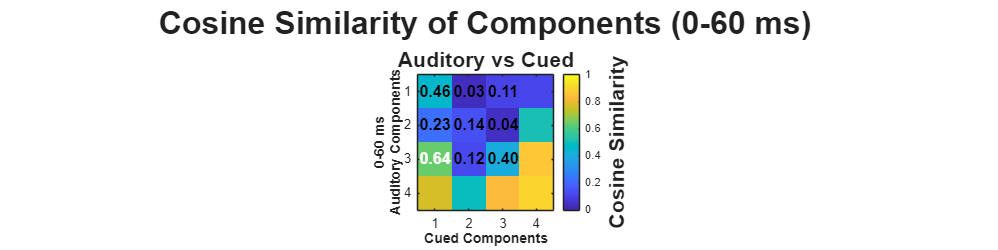

% Define the time axis in milliseconds
time_ms = time_ms_eeg * 1000; 

% Define relative time windows (post-tactile stimulus) in ms
time_windows_relative = {[0, 60], [60, 200], [200, 500]};
window_names = {'0-60 ms', '60-200 ms', '200-500 ms'};

% The conditions to compare against BLT (or BLA)
compare_conds = {'P1'};
ref_cond = 'BLA';

% We will compare the top 4 principal components
num_comps = 4; 

% Pre-allocate storage for similarities: struct -> window -> matrix
cos_sim_results = struct();

for c = 1:length(compare_conds)
    tgt_cond = compare_conds{c};
    tgt_onset_ms = 500; % for all conditions at 0.5 sec
    
    % Reference onset is always 500ms for BLA/BLT
    ref_onset_ms = 500; 
    
    for w = 1:length(time_windows_relative)
        win = time_windows_relative{w};
        
        % Convert ms windows into discrete sample offsets 
        sample_offset_start = round(win(1) / 1000 * fs);
        sample_offset_end   = round(win(2) / 1000 * fs);
        
        % Find the exact center index for the onsets
        ref_idx_center = find(time_ms >= ref_onset_ms, 1);
        tgt_idx_center = find(time_ms >= tgt_onset_ms, 1);
        
        % Create the sample range for this window
        ref_idx_range = (ref_idx_center + sample_offset_start) : (ref_idx_center + sample_offset_end);
        tgt_idx_range = (tgt_idx_center + sample_offset_start) : (tgt_idx_center + sample_offset_end);
        
        % Extract the [comp x time] data for the specified window
        comp_ref = pca_results.(ref_cond).comp_time(1:num_comps, ref_idx_range);
        comp_tgt = pca_results.(tgt_cond).comp_time(1:num_comps, tgt_idx_range);
        
        % Compute pairwise Cosine Similarity (1 - cosine distance)
        cos_dist = pdist2(comp_ref, comp_tgt, 'cosine');
        cos_sim_matrix = 1 - cos_dist; 
        cos_sim_matrix_abs = abs(cos_sim_matrix);
        cos_sim_results.(tgt_cond).(sprintf('win_%d', w)) = cos_sim_matrix_abs;
    end
end

%% Helper Function for Clean Titles
% This translates internal codes to publication-ready strings
get_clean_name = @(name) ...
    strrep(strrep(strrep(strrep(strrep(strrep(strrep(name, ...
    'BLA', 'Auditory'), ...
    'BLT', 'Tactile'), ...
    'P1', 'Cued'), ...
    'P2_500', 'Unpred. 500'), ...
    'P2_2000', 'Unpred. 2000'), ...
    'P3_500', 'Rand. Cued 500'), ...
    'P3_missing', 'Rand. Cued Missing');

%% Figure 1: 0-60 ms Window
% Create a shorter figure for the single row
figure('Position', [100, 100, 2000, 500], 'Name', 'PCA Cosine Similarity: 0-60ms');
t1 = tiledlayout(1, length(compare_conds), 'TileSpacing', 'compact', 'Padding', 'compact');

w = 1; % Target the 0-60 ms window
ref_name = get_clean_name(ref_cond); % Clean reference name

for c = 1:length(compare_conds)
    tgt_cond = compare_conds{c};
    tgt_name = get_clean_name(tgt_cond); % Clean target name
    nexttile;
    
    sim_mat = cos_sim_results.(tgt_cond).(sprintf('win_%d', w));
    
    imagesc(sim_mat);
    colormap('parula'); 
    caxis([0 1]); 
    axis square;
    xticks(1:num_comps);
    yticks(1:num_comps);
    
    % Overlay values for Top 3 Components
    for row = 1:min(3, num_comps)
        for col = 1:min(3, num_comps)
            val = sim_mat(row, col);
            if val > 0.55
                txt_color = 'w';
            else
                txt_color = 'k';
            end
            text(col, row, sprintf('%.2f', val), 'Color', txt_color, ...
                'HorizontalAlignment', 'center', 'FontSize', 12, 'FontWeight', 'bold');
        end
    end
    
    % Formatting for a single-row layout (using clean names)
    xlabel(sprintf('%s Components', tgt_name), 'Interpreter', 'none', 'FontWeight', 'bold');
    title(sprintf('%s vs %s', ref_name, tgt_name), 'Interpreter', 'none', 'FontSize', 16);
    
    if c == 1
        ylabel(sprintf('%s\n%s Components', window_names{w}, ref_name), 'Interpreter', 'none', 'FontWeight', 'bold');
    else
        yticklabels({});
    end
    
    if c == length(compare_conds)
        cb = colorbar;
        cb.Label.String = 'Cosine Similarity';
        cb.Label.FontSize = 16;
        cb.Label.FontWeight = 'bold';
    end
end
title(t1, 'Cosine Similarity of Components (0-60 ms)', 'FontSize', 24, 'FontWeight', 'bold');

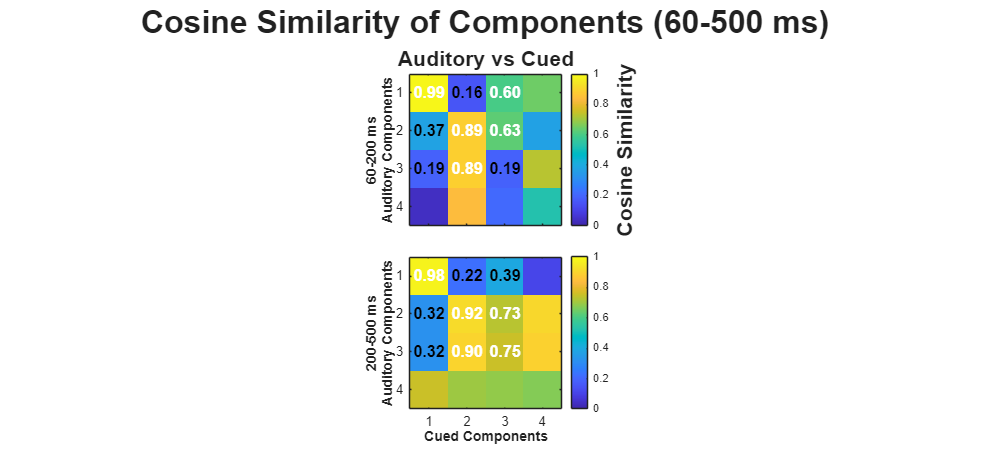



%% Figure 2: 60-200 ms & 200-500 ms Windows
% Create a taller figure for the two rows
figure('Position', [100, 600, 2000, 900], 'Name', 'PCA Cosine Similarity: 60-500ms');
t2 = tiledlayout(2, length(compare_conds), 'TileSpacing', 'compact', 'Padding', 'compact');

windows_to_plot = [2, 3]; % Target the 60-200 and 200-500 ms windows

for w_idx = 1:length(windows_to_plot)
    w = windows_to_plot(w_idx);
    for c = 1:length(compare_conds)
        tgt_cond = compare_conds{c};
        tgt_name = get_clean_name(tgt_cond); % Clean target name
        nexttile;
        
        sim_mat = cos_sim_results.(tgt_cond).(sprintf('win_%d', w));
        
        imagesc(sim_mat);
        colormap('parula'); 
        caxis([0 1]); 
        axis square;
        xticks(1:num_comps);
        yticks(1:num_comps);
        
        % Overlay values for Top 3 Components
        for row = 1:min(3, num_comps)
            for col = 1:min(3, num_comps)
                val = sim_mat(row, col);
                if val > 0.55
                    txt_color = 'w';
                else
                    txt_color = 'k';
                end
                text(col, row, sprintf('%.2f', val), 'Color', txt_color, ...
                    'HorizontalAlignment', 'center', 'FontSize', 12, 'FontWeight', 'bold');
            end
        end
        
        % Formatting for a multi-row layout (using clean names)
        if w == windows_to_plot(end)
            xlabel(sprintf('%s Components', tgt_name), 'Interpreter', 'none', 'FontWeight', 'bold');
        else
            xticklabels({});
        end
        
        if c == 1
            ylabel(sprintf('%s\n%s Components', window_names{w}, ref_name), 'Interpreter', 'none', 'FontWeight', 'bold');
        else
            yticklabels({});
        end
        
        if w == windows_to_plot(1)
            title(sprintf('%s vs %s', ref_name, tgt_name), 'Interpreter', 'none', 'FontSize', 16);
        end
        
        if c == length(compare_conds)
            cb = colorbar;
            if w == windows_to_plot(1) 
                cb.Label.String = 'Cosine Similarity';
                cb.Label.FontSize = 16;
                cb.Label.FontWeight = 'bold';
            end
        end
    end
end
title(t2, 'Cosine Similarity of Components (60-500 ms)', 'FontSize', 24, 'FontWeight', 'bold');

## 3.1 Cosine Similarity Setup & Calculation between P1 and target conditions (Auditory onset)


% Define the time axis in milliseconds
time_ms = time_ms_eeg * 1000; 

% Define relative time windows (post-stimulus) in ms
time_windows_relative = {[0, 60], [60, 200], [200, 500]};
window_names = {'0-60 ms', '60-200 ms', '200-500 ms'};

% --- NEW CONFIGURATION ---
ref_cond = 'P1'; % P1 (Cued) is the reference space

% Group the target conditions exactly as requested
group1 = {'P1_on_BLT', 'P1_on_BLA'}; % Projected P1 data onto Baseline PCs
group2 = {'P2_500_on_P1', 'P2_2000_on_P1', 'P2_on_P1'};
group3 = {'P3_500_on_P1', 'P3_missing_on_P1', 'P3_on_P1'};

% Combine them into one list for the calculation loop
all_targets = [group1, group2, group3];

% We will compare the top 4 principal components
num_comps = 4; 

% Pre-allocate storage
cos_sim_results = struct();

for c = 1:length(all_targets)
    tgt_cond = all_targets{c};
    
    % Define the absolute onset time for the TARGET condition
    tgt_onset_ms = 500;
    % Reference onset is always 500ms for P1
    ref_onset_ms = 500; 
    
    for w = 1:length(time_windows_relative)
        win = time_windows_relative{w};
        
        % Convert ms windows into discrete sample offsets
        sample_offset_start = round(win(1) / 1000 * fs);
        sample_offset_end   = round(win(2) / 1000 * fs);
        
        % Find the exact center index for the onsets
        ref_idx_center = find(time_ms >= ref_onset_ms, 1);
        tgt_idx_center = find(time_ms >= tgt_onset_ms, 1);
        
        % Create the sample range for this window
        ref_idx_range = (ref_idx_center + sample_offset_start) : (ref_idx_center + sample_offset_end);
        tgt_idx_range = (tgt_idx_center + sample_offset_start) : (tgt_idx_center + sample_offset_end);
        
        % Extract the [comp x time] data for REFERENCE (from pca_results)
        comp_ref = pca_results.(ref_cond).comp_time(1:num_comps, ref_idx_range);
        
        % --- Extract the [comp x time] data for TARGET ---
        if isfield(pca_results, tgt_cond)
            comp_tgt = pca_results.(tgt_cond).comp_time(1:num_comps, tgt_idx_range);
        elseif isfield(projections, tgt_cond)
            comp_tgt = projections.(tgt_cond)(1:num_comps, tgt_idx_range);
        else
            error('Condition %s not found in pca_results or projections!', tgt_cond);
        end
        
        % Compute pairwise Cosine Similarity
        cos_dist = pdist2(comp_ref, comp_tgt, 'cosine');
        cos_sim_matrix = 1 - cos_dist; % Convert distance to similarity [-1 to 1]
        cos_sim_matrix_abs = abs(cos_sim_matrix);
        cos_sim_results.(tgt_cond).(sprintf('win_%d', w)) = cos_sim_matrix_abs;
    end
end

%% Helper Function for Clean Titles
% Evaluates in order from longest to shortest to prevent partial overwrites
get_clean_name = @(name) strrep(strrep(strrep(strrep(strrep(strrep(strrep(strrep(strrep(strrep(strrep(name, ...
    '_on_P1', ''), ... % STRIP P1 PROJECTION TAG FOR GROUPS 2 & 3
    '_on_', ' on '), ... % TRANSLATE FOR GROUP 1 (e.g., Cued on Tactile)
    'P3_missing', 'Rand. Missing'), ...
    'P3_500', 'Rand. 500'), ...
    'P2_2000', 'Unpred. 2000'), ...
    'P2_500', 'Unpred. 500'), ...
    'P3', 'Rand. Cued'), ...
    'P2', 'Unpred.'), ...
    'P1', 'Cued'), ...
    'BLA', 'Auditory'), ...
    'BLT', 'Tactile');

%% 2.2 Heatmaps for cosine similarity (Grouped & Split by Time Window)
disp('Plotting Heatmaps...');

Plotting Heatmaps...


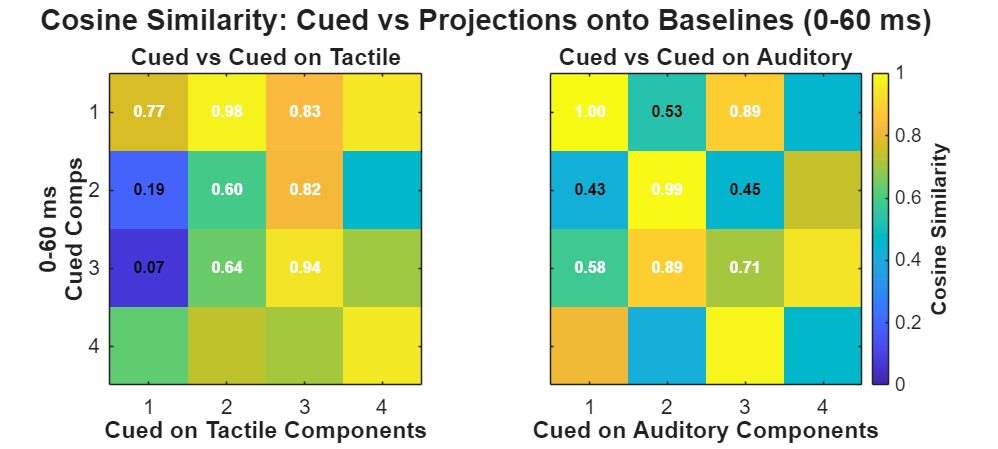

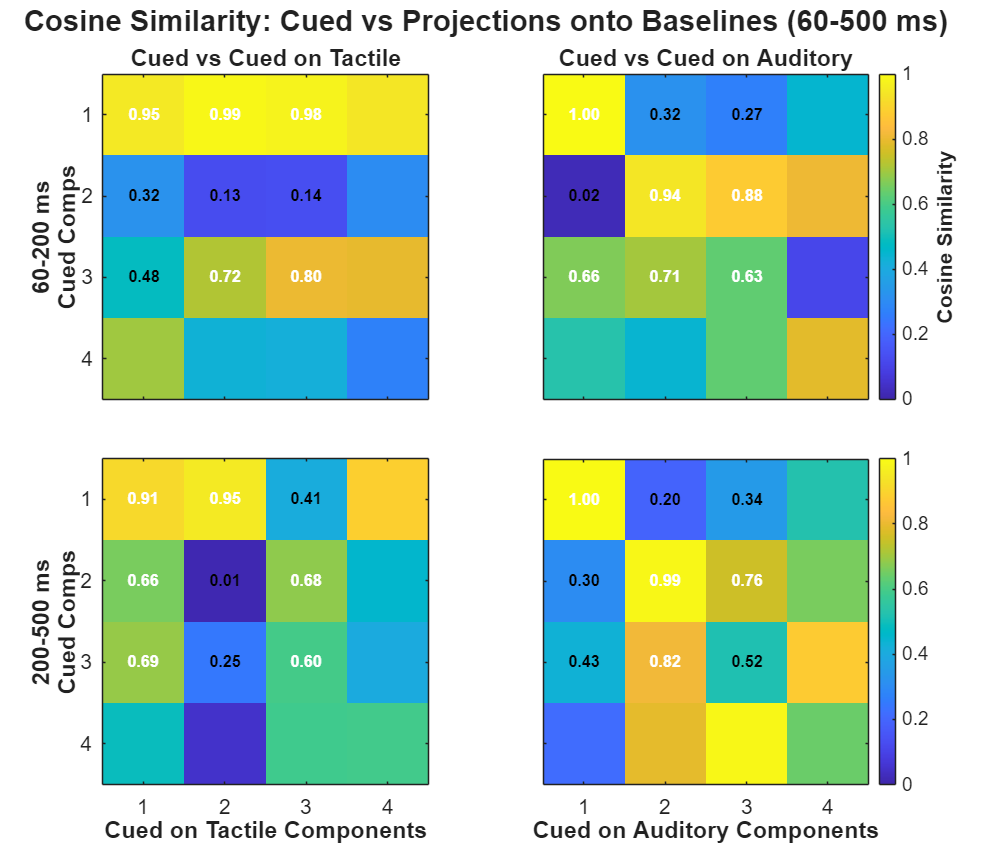

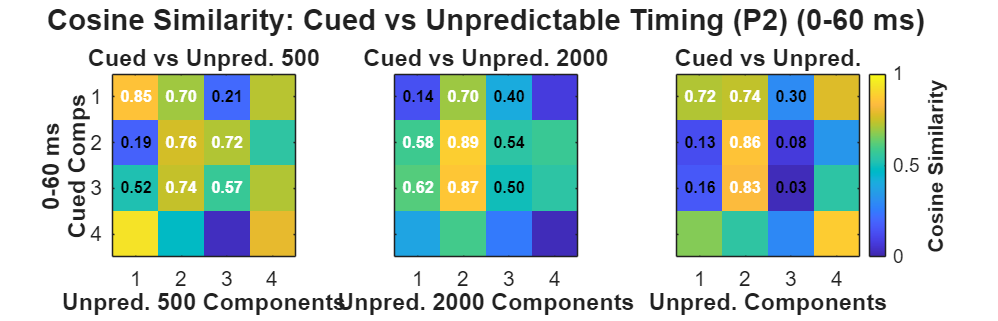

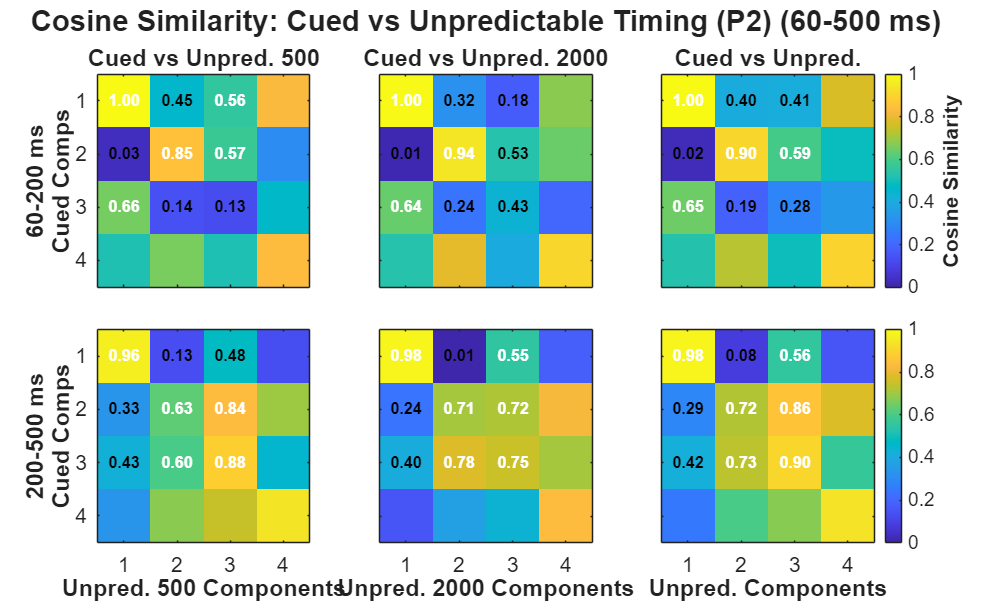

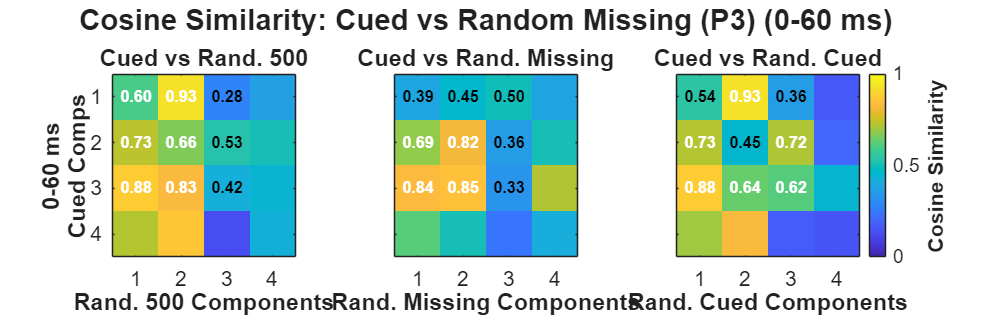

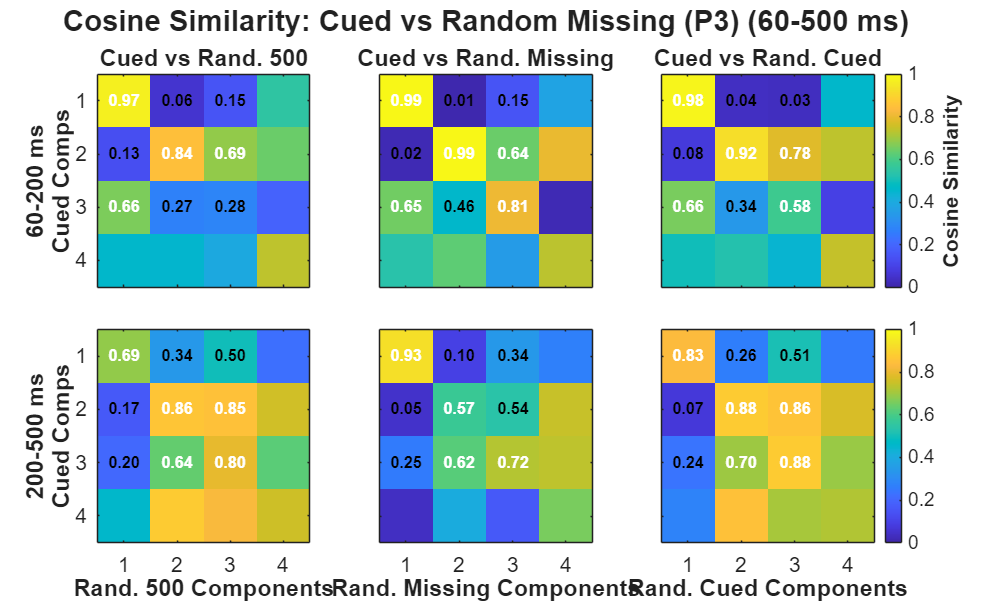


% Organize the groups and titles for the figures
plot_groups = {group1, group2, group3};
group_titles = {
    'Cued vs Projections onto Baselines', 
    'Cued vs Unpredictable Timing (P2)', 
    'Cued vs Random Missing (P3)'
};

% Get the clean reference name once (Will map 'P1' -> 'Cued')
clean_ref = get_clean_name(ref_cond);

% Loop through each condition group
for g = 1:length(plot_groups)
    current_group = plot_groups{g};
    base_title = group_titles{g};
    
    % Dynamic width based on the number of conditions in this group
    fig_width = 400 * length(current_group) + 200; 
    
    % =====================================================================
    % FIGURE A: 0-60 ms Window (w = 1)
    % =====================================================================
    fig_pos_A = [50 + (g*30), 50 + (g*30), fig_width, 450];
    figure('Position', fig_pos_A, 'Name', sprintf('Group %d: 0-60ms', g));
    
    t1 = tiledlayout(1, length(current_group), 'TileSpacing', 'compact', 'Padding', 'compact');
    w = 1; % Target the 0-60 ms window
    
    for c = 1:length(current_group)
        tgt_cond = current_group{c};
        clean_tgt = get_clean_name(tgt_cond); % Translate label (e.g. Cued on Auditory)
        nexttile;
        
        sim_mat = cos_sim_results.(tgt_cond).(sprintf('win_%d', w));
        
        imagesc(sim_mat);
        colormap('parula'); 
        caxis([0 1]);     
        axis square;
        xticks(1:num_comps);
        yticks(1:num_comps);
        
        % --- Text Overlay for Top 3x3 Components ---
        for row = 1:min(3, num_comps)
            for col = 1:min(3, num_comps)
                val = sim_mat(row, col);
                if val > 0.55
                    txt_color = 'w'; % White text on dark/high-value background
                else
                    txt_color = 'k'; % Black text on light/low-value background
                end
                text(col, row, sprintf('%.2f', val), 'Color', txt_color, ...
                    'HorizontalAlignment', 'center', 'FontSize', 12, 'FontWeight', 'bold');
            end
        end
        
        % Formatting using Clean Names
        xlabel(sprintf('%s Components', clean_tgt), 'Interpreter', 'none', 'FontWeight', 'bold');
        title(sprintf('%s vs %s', clean_ref, clean_tgt), 'Interpreter', 'none', 'FontSize', 16);
        
        if c == 1
            ylabel(sprintf('%s\n%s Comps', window_names{w}, clean_ref), 'Interpreter', 'none', 'FontWeight', 'bold');
        else
            yticklabels({});
        end
        
        if c == length(current_group)
            cb = colorbar;
            cb.Label.String = 'Cosine Similarity';
            cb.Label.FontWeight = 'bold';
            cb.Label.FontSize = 16;
        end
        set(gca,'FontSize',16);
    end
    title(t1, sprintf('Cosine Similarity: %s (0-60 ms)', base_title), 'FontSize', 22, 'FontWeight', 'bold');

    % =====================================================================
    % FIGURE B: 60-200 ms and 200-500 ms Windows (w = 2, 3)
    % =====================================================================
    fig_pos_B = [50 + (g*30), 550 + (g*30), fig_width, 850];
    figure('Position', fig_pos_B, 'Name', sprintf('Group %d: 60-500ms', g));
    
    t2 = tiledlayout(2, length(current_group), 'TileSpacing', 'compact', 'Padding', 'compact');
    windows_to_plot = [2, 3]; 
    
    for w_idx = 1:length(windows_to_plot)
        w = windows_to_plot(w_idx);
        for c = 1:length(current_group)
            tgt_cond = current_group{c};
            clean_tgt = get_clean_name(tgt_cond); % Translate label
            nexttile;
            
            sim_mat = cos_sim_results.(tgt_cond).(sprintf('win_%d', w));
            
            imagesc(sim_mat);
            colormap('parula'); 
            caxis([0 1]);     
            axis square;
            xticks(1:num_comps);
            yticks(1:num_comps);
            
            % --- Text Overlay for Top 3x3 Components ---
            for row = 1:min(3, num_comps)
                for col = 1:min(3, num_comps)
                    val = sim_mat(row, col);
                    if val > 0.55
                        txt_color = 'w';
                    else
                        txt_color = 'k';
                    end
                    text(col, row, sprintf('%.2f', val), 'Color', txt_color, ...
                        'HorizontalAlignment', 'center', 'FontSize', 12, 'FontWeight', 'bold');
                end
            end
            
            % Formatting using Clean Names
            if w == windows_to_plot(end)
                xlabel(sprintf('%s Components', clean_tgt), 'Interpreter', 'none', 'FontWeight', 'bold');
            else
                xticklabels({});
            end
            
            if c == 1
                ylabel(sprintf('%s\n%s Comps', window_names{w}, clean_ref), 'Interpreter', 'none', 'FontWeight', 'bold');
            else
                yticklabels({});
            end
            
            if w == windows_to_plot(1)
                title(sprintf('%s vs %s', clean_ref, clean_tgt), 'Interpreter', 'none', 'FontSize', 16);
            end
            
            if c == length(current_group)
                cb = colorbar;
                if w == windows_to_plot(1) % Label only the top colorbar for symmetry
                    cb.Label.String = 'Cosine Similarity';
                    cb.Label.FontWeight = 'bold';
                    cb.Label.FontSize = 16;
                end
            end
            set(gca,'FontSize',16);
        end
    end
    title(t2, sprintf('Cosine Similarity: %s (60-500 ms)', base_title), 'FontSize', 22, 'FontWeight', 'bold');
end

## 3.2 Cosine similarity between P1 and target conditions (Tactile Onset)


disp('Calculating Cosine Similarities (Tactile Onsets)...');

Calculating Cosine Similarities (Tactile Onsets)...



% Define the time axis in milliseconds
time_ms = time_ms_eeg * 1000; 

% Define relative time windows (post-tactile stimulus) in ms
time_windows_relative = {[0, 60], [60, 200], [200, 500]};
window_names = {'0-60 ms', '60-200 ms', '200-500 ms'};

% --- NEW CONFIGURATION ---
ref_cond = 'P1'; % P1 is the reference space

% Group the target conditions using their PROJECTIONS onto P1
group1 = {'P1_on_BLT', 'P1_on_BLA'};
group2 = {'P2_500_on_P1', 'P2_2000_on_P1', 'P2_on_P1'};
group3 = {'P3_500_on_P1', 'P3_missing_on_P1', 'P3_on_P1'};

% Combine them into one list for the calculation loop
all_targets = [group1, group2, group3];

% We will compare the top 4 principal components
num_comps = 4; 

% Pre-allocate storage
cos_sim_results = struct();

for c = 1:length(all_targets)
    tgt_cond = all_targets{c};
    
    % Define the absolute onset time for the TARGET condition (Tactile)
    if contains(tgt_cond, 'P2_2000')
        tgt_onset_ms = 2500; 
    else
        tgt_onset_ms = 1000; % 1.0s tactile onset for everything else
    end
    
    % Reference tactile onset is always 1000ms for P1
    ref_onset_ms = 1000; 
    
    for w = 1:length(time_windows_relative)
        win = time_windows_relative{w};
        
        % Convert ms windows into discrete sample offsets
        sample_offset_start = round(win(1) / 1000 * fs);
        sample_offset_end   = round(win(2) / 1000 * fs);
        
        % Find the exact center index for the onsets
        ref_idx_center = find(time_ms >= ref_onset_ms, 1);
        tgt_idx_center = find(time_ms >= tgt_onset_ms, 1);
        
        % Create the sample range for this window
        ref_idx_range = (ref_idx_center + sample_offset_start) : (ref_idx_center + sample_offset_end);
        tgt_idx_range = (tgt_idx_center + sample_offset_start) : (tgt_idx_center + sample_offset_end);
        
        % Extract the [comp x time] data for REFERENCE
        comp_ref = pca_results.(ref_cond).comp_time(1:num_comps, ref_idx_range);
        
        % Extract the [comp x time] data for TARGET (from projections)
        if isfield(pca_results, tgt_cond)
            comp_tgt = pca_results.(tgt_cond).comp_time(1:num_comps, tgt_idx_range);
        elseif isfield(projections, tgt_cond)
            comp_tgt = projections.(tgt_cond)(1:num_comps, tgt_idx_range);
        else
            error('Condition %s not found in pca_results or projections!', tgt_cond);
        end
        
        % Compute pairwise Cosine Similarity
        cos_dist = pdist2(comp_ref, comp_tgt, 'cosine');
        cos_sim_matrix = 1 - cos_dist; % Convert distance to similarity [-1 to 1]
        cos_sim_matrix_abs = abs(cos_sim_matrix);
        cos_sim_results.(tgt_cond).(sprintf('win_%d', w)) = cos_sim_matrix_abs;
    end
end

%% Helper Function for Clean Titles
get_clean_name = @(name) strrep(strrep(strrep(strrep(strrep(strrep(strrep(strrep(strrep(strrep(strrep(name, ...
    '_on_P1', ''), ...
    '_on_', ' on '), ... 
    'P3_missing', 'Rand. Missing'), ...
    'P3_500', 'Rand. 500'), ...
    'P2_2000', 'Unpred. 2000'), ...
    'P2_500', 'Unpred. 500'), ...
    'P3', 'Rand. Cued'), ...
    'P2', 'Unpred.'), ...
    'P1', 'Cued'), ...
    'BLA', 'Auditory'), ...
    'BLT', 'Tactile');

%% 2.2 Heatmaps for cosine similarity (Grouped into 3 Figures)
disp('Plotting Heatmaps...');

Plotting Heatmaps...


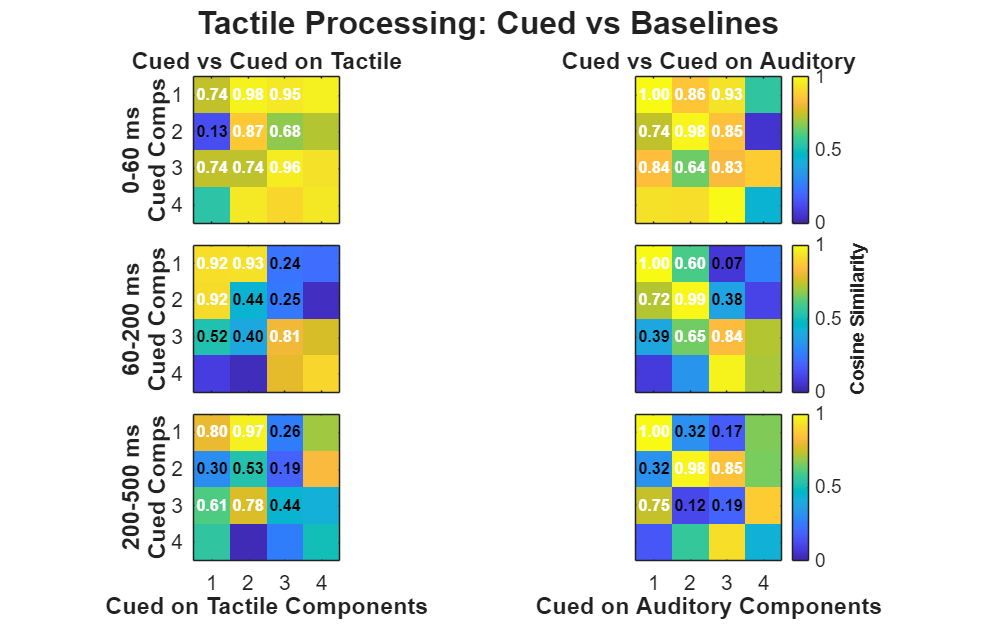

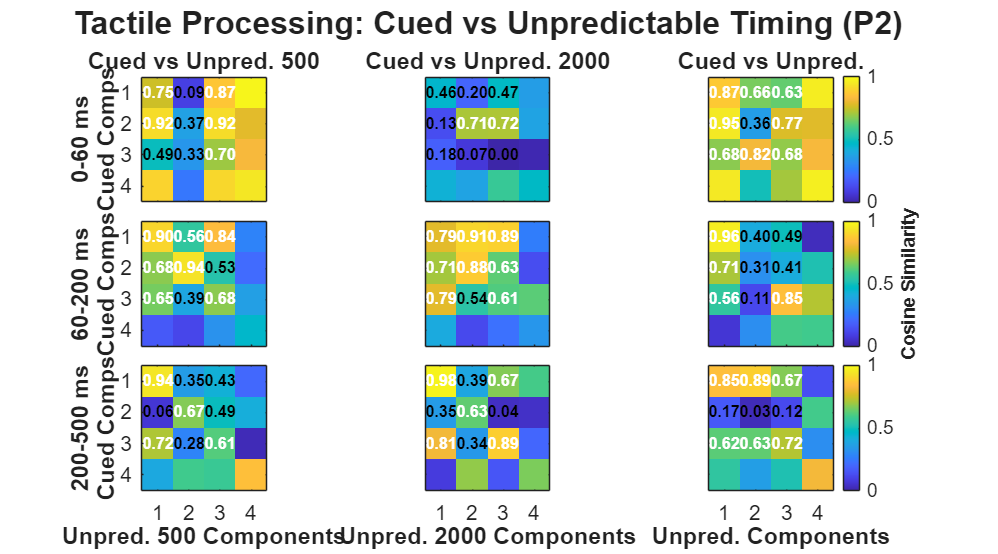

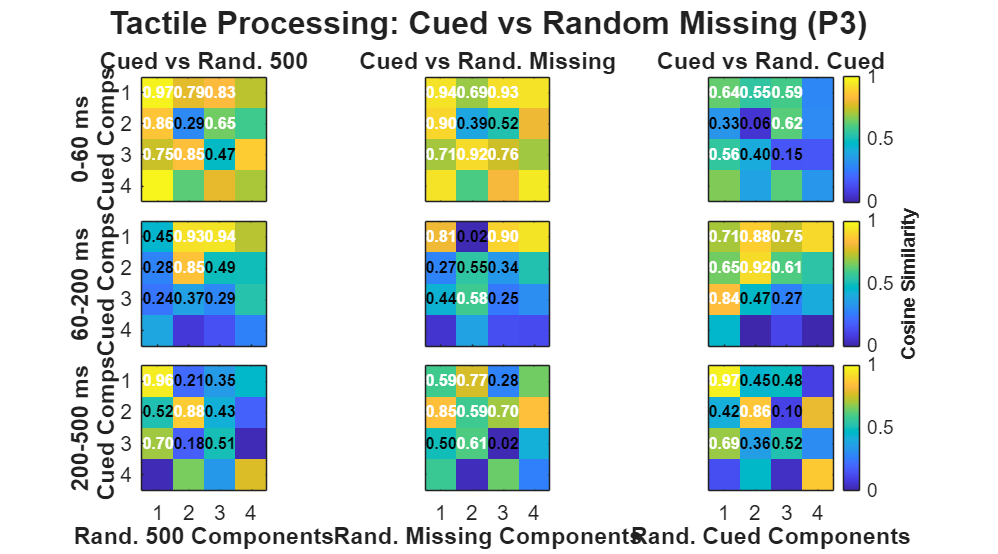


% Organize the groups and titles for the figures
plot_groups = {group1, group2, group3};
group_titles = {
    'Tactile Processing: Cued vs Baselines', 
    'Tactile Processing: Cued vs Unpredictable Timing (P2)', 
    'Tactile Processing: Cued vs Random Missing (P3)'
};

% Get the clean reference name once
clean_ref = get_clean_name(ref_cond);

% Generate a separate figure for each group
for g = 1:length(plot_groups)
    current_group = plot_groups{g};
    base_title = group_titles{g};
    
    % Offset figure positions slightly so they don't completely overlap
    fig_pos = [50 + (g*30), 50 + (g*30), 1200 + (length(current_group)*200), 1000];
    figure('Position', fig_pos, 'Name', sprintf('PCA Cosine Sim - Group %d', g));
    
    % Layout: Rows = Time Windows, Columns = Target Conditions
    t = tiledlayout(length(time_windows_relative), length(current_group), 'TileSpacing', 'compact', 'Padding', 'compact');
    
    for w = 1:length(time_windows_relative)
        for c = 1:length(current_group)
            tgt_cond = current_group{c};
            clean_tgt = get_clean_name(tgt_cond);
            
            nexttile;
            
            % Get the similarity matrix
            sim_mat = cos_sim_results.(tgt_cond).(sprintf('win_%d', w));
            
            % Plot heatmap
            imagesc(sim_mat);
            colormap('parula'); 
            caxis([0 1]);     
            
            % Formatting
            axis square;
            xticks(1:num_comps);
            yticks(1:num_comps);
            
            % --- Text Overlay for Top 3x3 Components ---
            for row = 1:min(3, num_comps)
                for col = 1:min(3, num_comps)
                    val = sim_mat(row, col);
                    if val > 0.55
                        txt_color = 'w';
                    else
                        txt_color = 'k';
                    end
                    text(col, row, sprintf('%.2f', val), 'Color', txt_color, ...
                        'HorizontalAlignment', 'center', 'FontSize', 12, 'FontWeight', 'bold');
                end
            end
            
            % X-axis labels strictly on the bottom row
            if w == length(time_windows_relative)
                xlabel(sprintf('%s Components', clean_tgt), 'Interpreter', 'none', 'FontWeight', 'bold');
            else
                xticklabels({});
            end
            
            % Y-axis labels strictly on the leftmost column
            if c == 1
                ylabel(sprintf('%s\n%s Comps', window_names{w}, clean_ref), 'Interpreter', 'none', 'FontWeight', 'bold');
            else
                yticklabels({});
            end
            
            % Titles strictly on the top row
            if w == 1
                title(sprintf('%s vs %s', clean_ref, clean_tgt), 'Interpreter', 'none', 'FontSize', 16);
            end
            
            % Colorbar only on the far right column
            if c == length(current_group)
                cb = colorbar;
                if w == round(length(time_windows_relative)/2) % Label the middle one for symmetry
                    cb.Label.String = 'Cosine Similarity';
                    cb.Label.FontWeight = 'bold';
                    cb.Label.FontSize = 14;
                end
            end
            set(gca,'FontSize',16);
        end
    end
    
    % Add the overarching title for the specific group
    title(t, base_title, 'FontSize', 24, 'FontWeight', 'bold');
end

## 4.0 Sliding Window PCA (20 msec) with Vector Alignment

disp('Performing Sliding Window PCA on BLA, BLT, and P1...');

Performing Sliding Window PCA on BLA, BLT, and P1...



pca_conditions = {'BLA', 'BLT', 'P1'};
num_comps = 4; 

% 1. Define Sliding Window Parameters
win_ms = 1000; 
step_ms = 300; % 5ms step gives a smooth 75% overlap.

% Convert ms to samples
if isempty(fs), fs = 512; end % Make sure your sampling rate is correct
win_samples = round((win_ms / 1000) * fs);
step_samples = round((step_ms / 1000) * fs);

total_samples = length(time_ms_eeg);
win_starts = 1:step_samples:(total_samples - win_samples + 1);
n_windows = length(win_starts);

% Calculate the center time of each window for plotting
time_windows = zeros(1, n_windows);

% Pre-allocate storage
pca_dynamic = struct();

for i = 1:length(pca_conditions)
    c_name = pca_conditions{i};
    X = data_grand_avg.(c_name); % Size: [num_ch x time]
    
    % Pre-allocate matrices to hold data across time windows
    coeffs_time = zeros(num_ch, num_comps, n_windows);
    exp_var_time = zeros(num_comps, n_windows);
    mu_time = zeros(num_ch, n_windows);
    comp_time_matrix = zeros(num_comps, n_windows); % <-- NEW: Pre-allocate comp_time
    
    prev_coeff = []; % Used to track and align signs
    
    for w = 1:n_windows
        % Define the exact sample range for this window
        idx = win_starts(w):(win_starts(w) + win_samples - 1);
        time_windows(w) = mean(time_ms_eeg(idx)); % Center of the window
        
        X_win = X(:, idx);
        
        % Perform PCA strictly on this 20ms chunk
        [coeff, score, ~, ~, exp_var, mu] = pca(X_win');
        
        % Keep only top components
        coeff = coeff(:, 1:min(num_comps, size(coeff,2)));
        score = score(:, 1:min(num_comps, size(score,2))); 
        exp_var = exp_var(1:min(num_comps, length(exp_var)));
        
        % --- ALIGNMENT STEP (Fixing Sign Ambiguity) ---
        if w > 1
            for pc = 1:size(coeff, 2)
                % Calculate dot product with the previous window's matching PC
                dp = dot(prev_coeff(:, pc), coeff(:, pc));
                if dp < 0
                    % If they point in opposite directions, flip the spatial weight
                    coeff(:, pc) = -coeff(:, pc);             
                    score(:, pc) = -score(:, pc); 
                end
            end
        end
        
        % Store data
        prev_coeff = coeff;
        coeffs_time(:, 1:size(coeff,2), w) = coeff;
        exp_var_time(1:length(exp_var), w) = exp_var;
        mu_time(:, w) = mu';
        
        % <-- NEW: Take the mean score across the 20ms window to represent this time point
        comp_time_matrix(1:size(score,2), w) = mean(score, 1)';
    end
    
    % Save to dynamic structure
    pca_dynamic.(c_name).coeffs = coeffs_time;        % [ch x comp x window]
    pca_dynamic.(c_name).exp_var = exp_var_time;      % [comp x window]
    pca_dynamic.(c_name).mu = mu_time;                % [ch x window]
    pca_dynamic.(c_name).comp_time = comp_time_matrix; % [comp x window]
end


fprintf('Completed PCA for %d overlapping sliding windows.\n', n_windows);

Completed PCA for 9 overlapping sliding windows.


## 4.1 Plot Explained Variance Across Sliding Windows

disp('Plotting Cumulative Explained Variance...');

Plotting Cumulative Explained Variance...


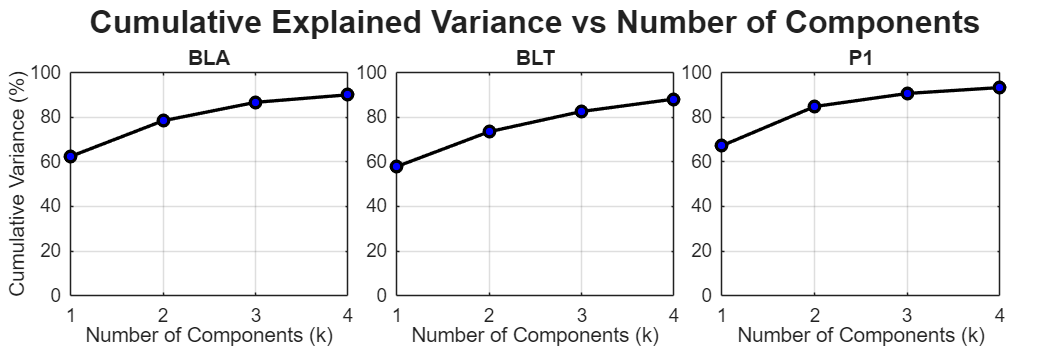


figure('Position', [50 50 1200 400], 'Name', 'Cumulative Variance');
t = tiledlayout(1, 3, 'TileSpacing', 'compact', 'Padding', 'compact');
title(t, 'Cumulative Explained Variance vs Number of Components', 'FontSize', 24, 'FontWeight', 'bold');

for i = 1:length(pca_conditions)
    c_name = pca_conditions{i};
    nexttile;
    
    % Average the explained variance across all sliding windows (Dim 2)
    mean_exp_var = mean(pca_dynamic.(c_name).exp_var, 2);
    
    % Calculate cumulative sum to get the total variance explained up to k
    cum_var = cumsum(mean_exp_var);
    
    % Plot the Pareto/Scree curve
    plot(1:num_comps, cum_var, '-ok', 'LineWidth', 2.5, 'MarkerFaceColor', 'b', 'MarkerSize', 8);
    
    xlim([1 num_comps]);
    ylim([0 100]); % Assuming explained variance is a percentage 0-100
    xticks(1:num_comps);
    
    xlabel('Number of Components (k)');
    if i == 1
        ylabel('Cumulative Variance (%)'); 
    end
    title(c_name, 'FontSize', 18);
    grid on; 
    set(gca,'FontSize',14);
end

## 4.2 Dynamic Cross-Condition Projections

disp('Projecting dynamically across sliding windows...');

Projecting dynamically across sliding windows...


dyn_projections = struct();

% We will define a helper function to project a specific condition's window
% onto a target space's corresponding temporal window
target_conds = {'P2', 'P3', 'P2_500', 'P3_500', 'P2_2000', 'P3_missing'};

for w = 1:n_windows
    idx = win_starts(w):(win_starts(w) + win_samples - 1);
    
    % 1. Project P1 onto BLA and BLT
    for ref = {'BLA', 'BLT'}
        ref_cond = ref{1};
        X_P1_win = data_grand_avg.P1(:, idx);
        mu_ref = pca_dynamic.(ref_cond).mu(:, w);
        coeff_ref = pca_dynamic.(ref_cond).coeffs(:, :, w);
        
        % Project: (Data - Mu) * Coeff
        score_proj = (X_P1_win' - mu_ref') * coeff_ref;
        
        % We take the mean score within this 20ms window to represent the time point
        dyn_projections.(sprintf('P1_on_%s', ref_cond))(:, w) = mean(score_proj, 1)';
    end
    
    % 2. Project P2 and P3 conditions onto P1
    for t_idx = 1:length(target_conds)
        tgt = target_conds{t_idx};
        X_tgt_win = data_grand_avg.(tgt)(:, idx);
        
        mu_P1 = pca_dynamic.P1.mu(:, w);
        coeff_P1 = pca_dynamic.P1.coeffs(:, :, w);
        
        score_proj = (X_tgt_win' - mu_P1') * coeff_P1;
        dyn_projections.(sprintf('%s_on_P1', tgt))(:, w) = mean(score_proj, 1)';
    end
end

disp('Plotting PCA Spatial Weights and Time-Courses for Multisensory Integration...');

Plotting PCA Spatial Weights and Time-Courses for Multisensory Integration...


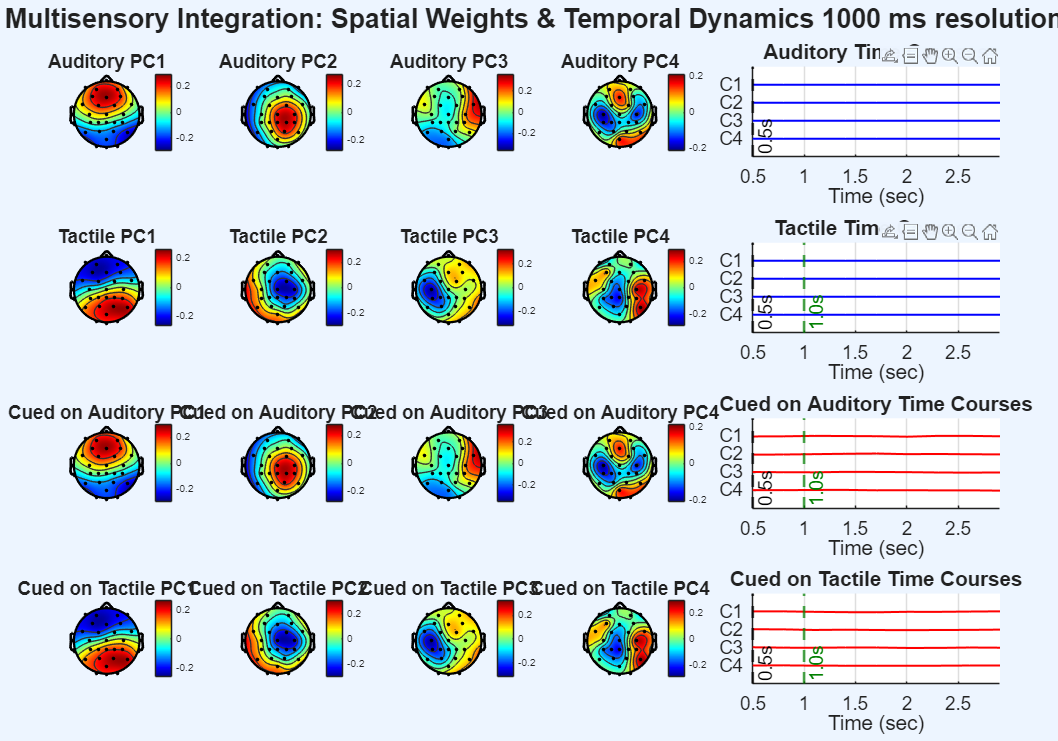


num_comps_plot = 4;
comp_offset = 30; 
tick_positions = (num_comps_plot - (1:num_comps_plot)) * comp_offset;
dark_green  = [0 0.5 0];

% Suppress all layout warnings from EEGLAB topoplot
warning('off', 'all');

% --- Define exactly the 4 rows we want to plot ---
ms_plot_conds = {'BLA', 'BLT', 'P1_on_BLA', 'P1_on_BLT'};

% --- FIGURE 1: Multisensory Integration ---
% Changed to a 4x6 layout to accommodate both P1 projections
figure('Position',[50 50 2000 1400], 'Name', 'Multisensory Integration PCA');
t1 = tiledlayout(4, 6, 'TileSpacing', 'compact', 'Padding', 'compact');
title(t1, sprintf('Multisensory Integration: Spatial Weights & Temporal Dynamics %d ms resolution', win_ms), 'FontSize', 20, 'FontWeight', 'bold');

for i = 1:length(ms_plot_conds)
    c_name = ms_plot_conds{i};
    
    % --- Intelligent Data Extraction & Naming ---
    if strcmp(c_name, 'BLA')
        % FIXED: Average the sliding spatial weights across time for the topoplot
        coeff = mean(pca_dynamic.BLA.coeffs, 3); 
        comp_time = pca_dynamic.BLA.comp_time;
        line_color = 'b';
        plot_name = 'Auditory';
        
    elseif strcmp(c_name, 'BLT')
        % FIXED: Average the sliding spatial weights across time for the topoplot
        coeff = mean(pca_dynamic.BLT.coeffs, 3); 
        comp_time = pca_dynamic.BLT.comp_time;
        line_color = 'b';
        plot_name = 'Tactile';
        
    elseif strcmp(c_name, 'P1_on_BLA')
        coeff = mean(pca_dynamic.BLA.coeffs, 3);          
        comp_time = dyn_projections.P1_on_BLA;      % Time course is P1
        line_color = 'r';                           % Red for projected data
        plot_name = 'Cued on Auditory';
        
    elseif strcmp(c_name, 'P1_on_BLT')
        coeff = mean(pca_dynamic.BLT.coeffs, 3);          
        comp_time = dyn_projections.P1_on_BLT;      % Time course is P1
        line_color = 'r';                           % Red for projected data
        plot_name = 'Cued on Tactile';
    end
    
    % 1. Plot 4 Topoplots for this condition
    for comp = 1:num_comps_plot
        nexttile;
        topoplot(coeff(:, comp), EEG.chanlocs, 'electrodes', 'on');
        title(sprintf('%s PC%d', plot_name, comp), 'FontSize', 14);
        colorbar;
    end
    
    % 2. Plot the Stacked Time Courses (Spanning 2 columns to give it width)
    nexttile([1 2]);
    hold on;
    for comp_idx = 1:num_comps_plot
        % Use time_windows instead of time_ms_eeg for the sliding resolution
        plot(time_windows, comp_time(comp_idx, :) + (num_comps_plot - comp_idx)*comp_offset, line_color, 'LineWidth', 1.5);
    end
    
    % --- Dynamic Event Lines ---
    xline(0.5, 'k--', '0.5s', 'LineWidth', 2, 'FontSize', 14, 'LabelVerticalAlignment', 'bottom'); % All have audio
    
    % Add tactile lines for BLT and both Cued projections
    if contains(c_name, 'BLT') || contains(c_name, 'P1')
        xline(1.0, '--', '1.0s', 'Color', dark_green, 'LineWidth', 2, 'FontSize', 14, 'LabelVerticalAlignment', 'bottom');
    end
    hold off;
    
    % Formatting
    xlim([min(time_windows), max(time_windows)]); 
    ylim([-comp_offset, num_comps_plot*comp_offset]);
    xlabel('Time (sec)'); 
    yticks(flip(tick_positions));
    yticklabels(flip(arrayfun(@(x) sprintf('C%d', x), 1:num_comps_plot, 'UniformOutput', false)));
    
    title(sprintf('%s Time Courses', plot_name), 'FontSize', 16);
    grid on;
    set(gca,'FontSize',14);
end


% Turn warnings back on
warning('on', 'all');